%% Compare channel responses for one eye across days. 
%  This will be used to evaluate consistency of responses across recording
%  sessions.

%  Set up directories.
addpath(genpath('/Volumes/BIGZINGY/BlackrockData'))                        % Data stored here.
addpath(genpath('/u/vnl/users/julia'))                                     % Analysis scripts & helper functions.
addpath(genpath('/Library/Application Support/MWorks/Scripting/Matlab'))   % Matlab support for Mworks (needed to run parser).

eye = 'LE';                                                                % LE = fellow eye, RE = amblyopic
arrayID = 'nsp1';                                                          % nsp1 = V1/V2, nsp2 = V4
nChan = 96;

dataDir = '/Volumes/BIGZINGY/BlackRockData/';
outputDir = [ '/Volumes/BIGZINGY/BlackRockData/' arrayID '/spikeBinned/'];
figureDir = [ '/Volumes/BIGZINGY/BlackRockData/' arrayID '/figures/'];
allRespFile = [outputDir '/WU_' eye '_' arrayID '_allResp.mat'];

parseOverwrite = 0;

%% Get list of experiment names.
D = dir(['/Volumes/BIGZINGY/BlackrockData/' arrayID '/' arrayID '_blackrock/']);   
D = extractfield(D, 'name')';
D = D(find(contains(D, eye)));
filenames = unique(strtok(D, '.'));
respfiles = strcat(outputDir, filenames, '_resp.mat');


## Load structure containing data from all days

A = load(allRespFile)

A = struct with fields:
                  JTS: [96×32 double]
                 aMap: [1×1 arraymap]
                files: {1×32 cell}
             goodChan: [96×32 double]
          maxChanResp: [96×32 double]
      respAvgOverTime: [30×96×32 double]
           respBinned: [6×6×96×32 double]
       respBinnedNorm: [6×6×96×32 double]
    respBlankOverTime: [30×96×32 double]



eye = 'LE';                                                                % LE = fellow eye, RE = amblyopic
arrayID = 'nsp1';                                                          % nsp1 = V1/V2, nsp2 = V4
nChan = 96;
nS = length(A.files);

% %% Build structure containing relevant responses across all days. 
%nS          = length(respfiles);                                           % number of recording sessions/files.
binStart    = 5;
binEnd      = 15;
nOri        = 6;
nSf         = 6;
nBins       = 30;                                                          % number of bins used in parsing (10 ms intervals)
% 
% respBinned          = NaN(nSf, nOri, nChan, nS);                           % Baseline subtracted. trial triggered avg. Binned/summed from 50-150 ms after stim on
% respBinnedNorm      = NaN(nSf, nOri, nChan, nS);
% maxChanResp         = NaN(nChan, nS);
% respAvgOverTime     = NaN(nBins, nChan, nS);                               % Averaged across all 'real' grating stimuli
% respBlankOverTime   = NaN(nBins, nChan, nS);                               % Average response to blank
% JTS                 = NaN(nChan, nS);
% goodChan            = NaN(nChan, nS);
% files               = cell(1, nS);
% 
% for iF = 1:nS
%     try
%         R   = load(respfiles{iF});
%         aMap = R.aMap;
%         for iC = 1:nChan
%             respBinned(:,:,iC,iF)   = nansum(R.respAvg(:,:,binStart:binEnd,iC), 3) - ...
%                 nansum(R.respBlank(iC,binStart:binEnd));
%             maxChanResp(iC,iF)      = max(max(respBinned(:,:,iC,iF)));
%             respBinnedNorm(:,:,iC,iF) = respBinned(:,:,iC,iF) ./ maxChanResp(iC,iF);
%             respAvgOverTime(:,iC,iF) = nanmean(nanmean(R.respAvg(:,:,:,iC)));
%             respBlankOverTime(:,iC,iF) = R.respBlank(iC,:);
%         end
%         JTS(:,iF) = R.JTS;
%         goodChan(:,iF) = R.JTS > 0.95;
%         files{iF} = filenames{iF};
%     catch
%         disp([filenames{iF} ' didnt work'])
%     end
% end
% 
% save(allRespFile, ...
%     'respBinned', 'respBinnedNorm', 'maxChanResp', 'respAvgOverTime', 'respBlankOverTime', ...
%     'JTS', 'goodChan', 'aMap', 'files')
% A = load(allRespFile)
% 

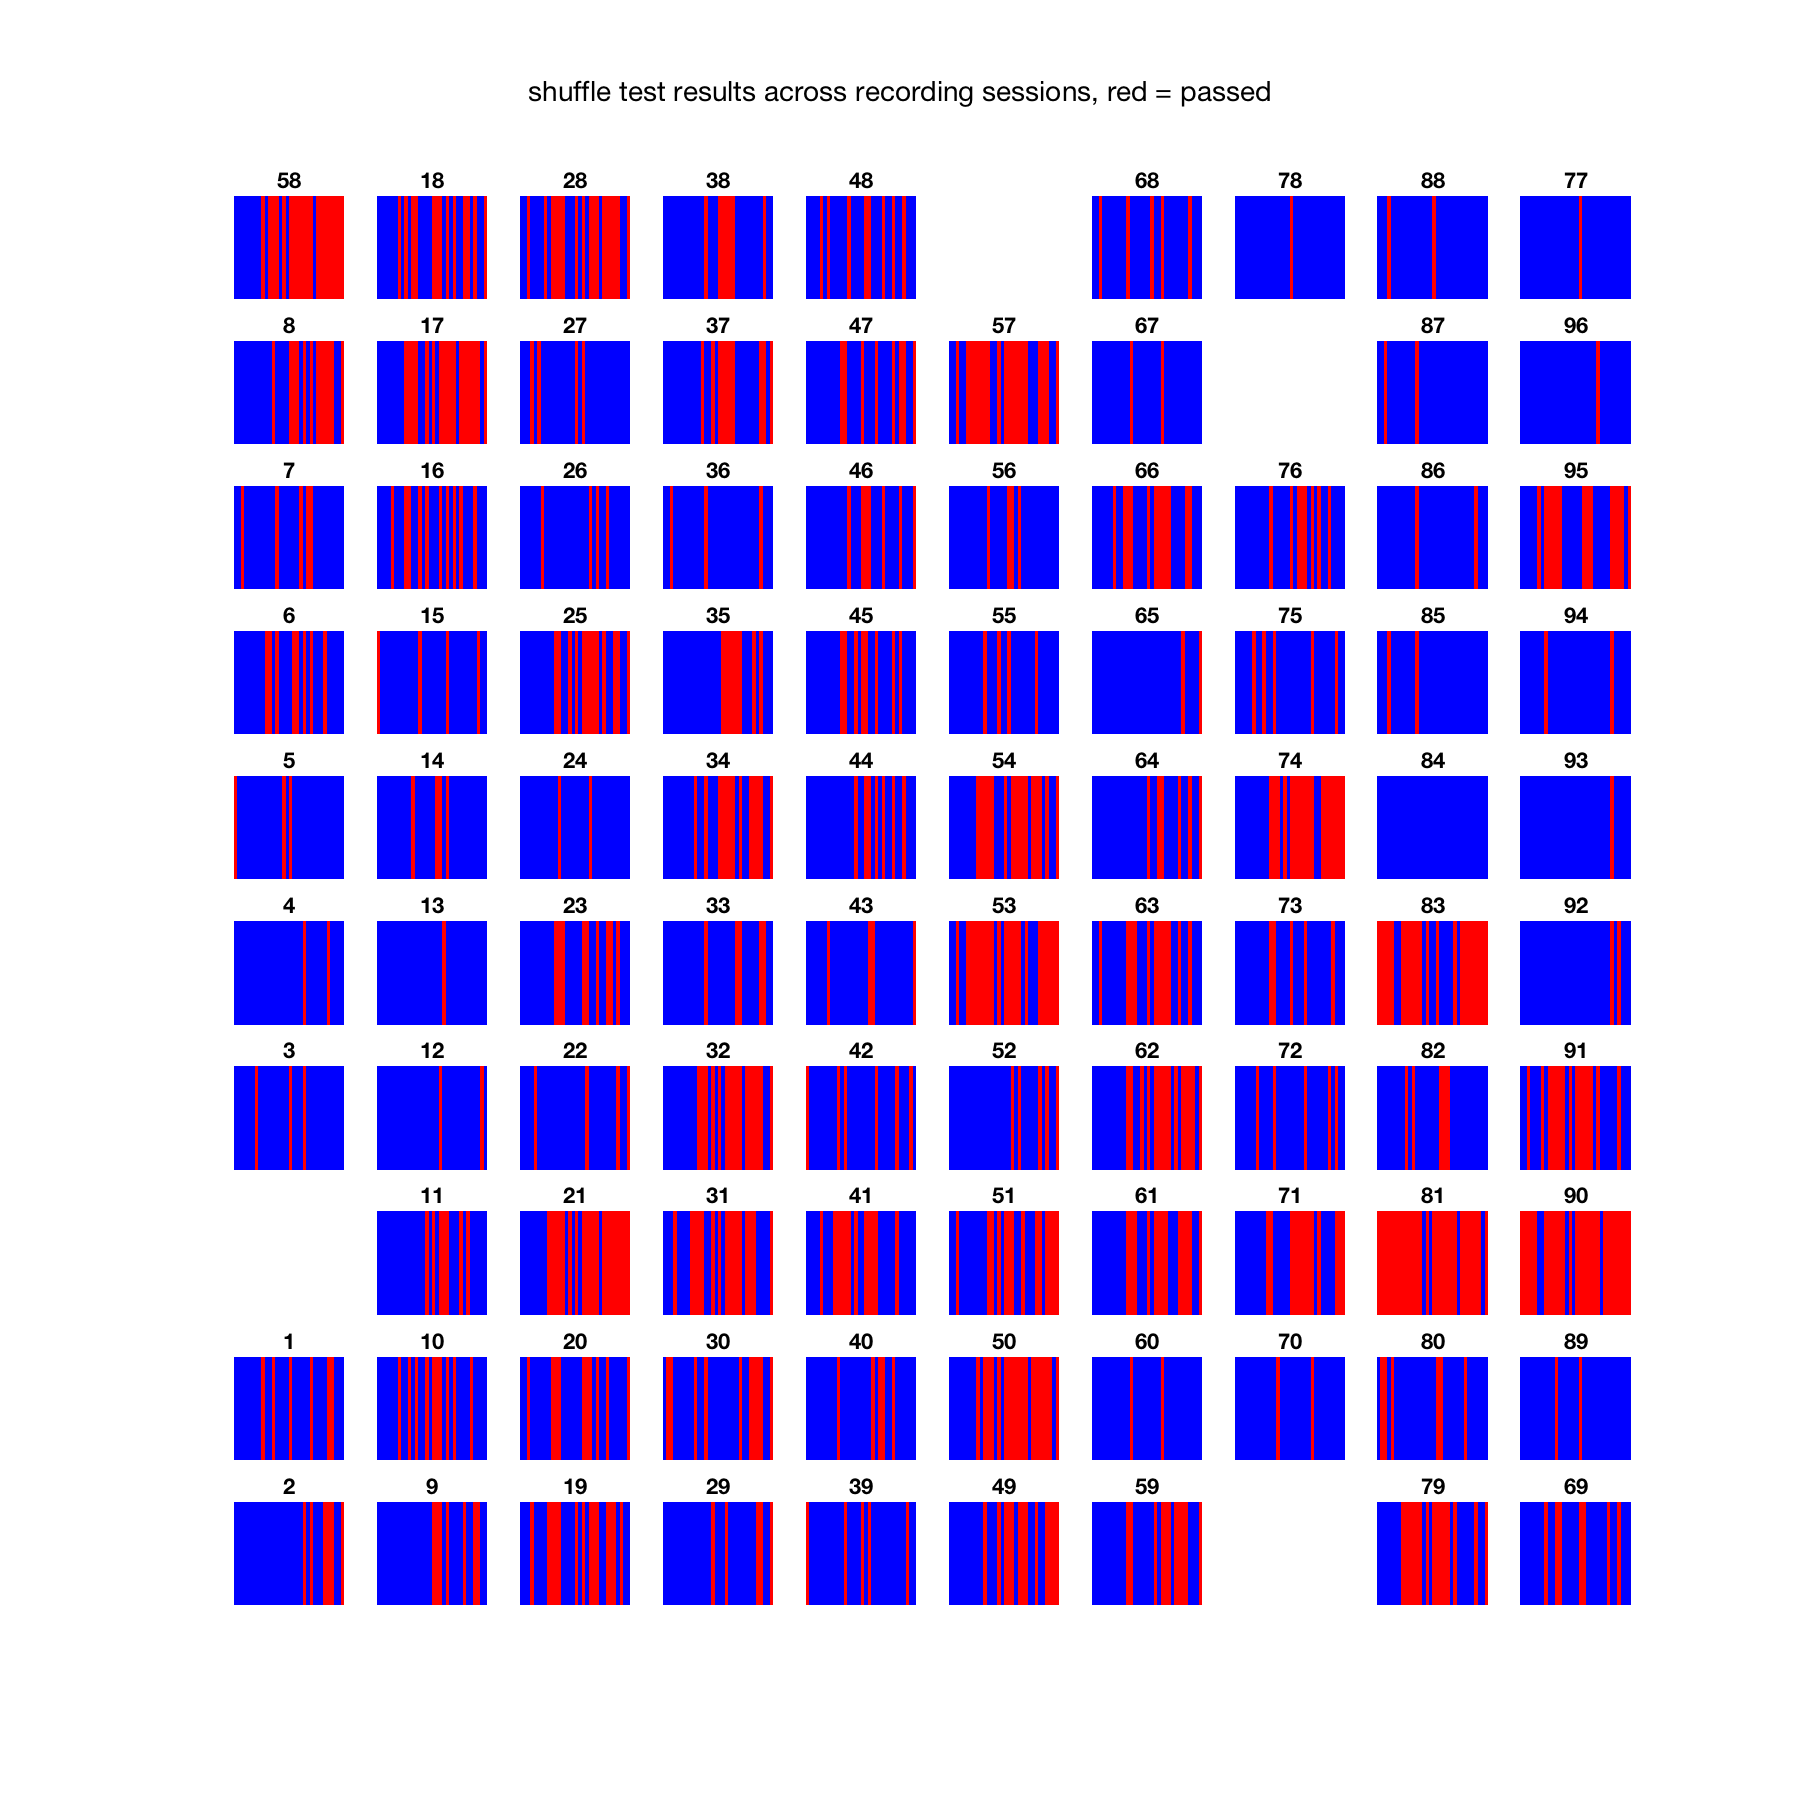

% Plot shuffle test results for each channel across days
figure; hold on
pos = get(gcf,'Position');
set(gcf,'Position',[pos(1) pos(2) 900 900])
for iC = 1:nChan
    nsubplot(10, 10, A.aMap.row(iC)+1, A.aMap.col(iC)+1);
    imagesc(A.goodChan(iC,:))
    colormap redblue
    caxis([0 1])
    axis tight; axis off
    set(gca, 'Position',get(gca, 'Position')+[0 0 0.001 0.001]);
    title(iC)
end
suptitle('shuffle test results across recording sessions, red = passed')

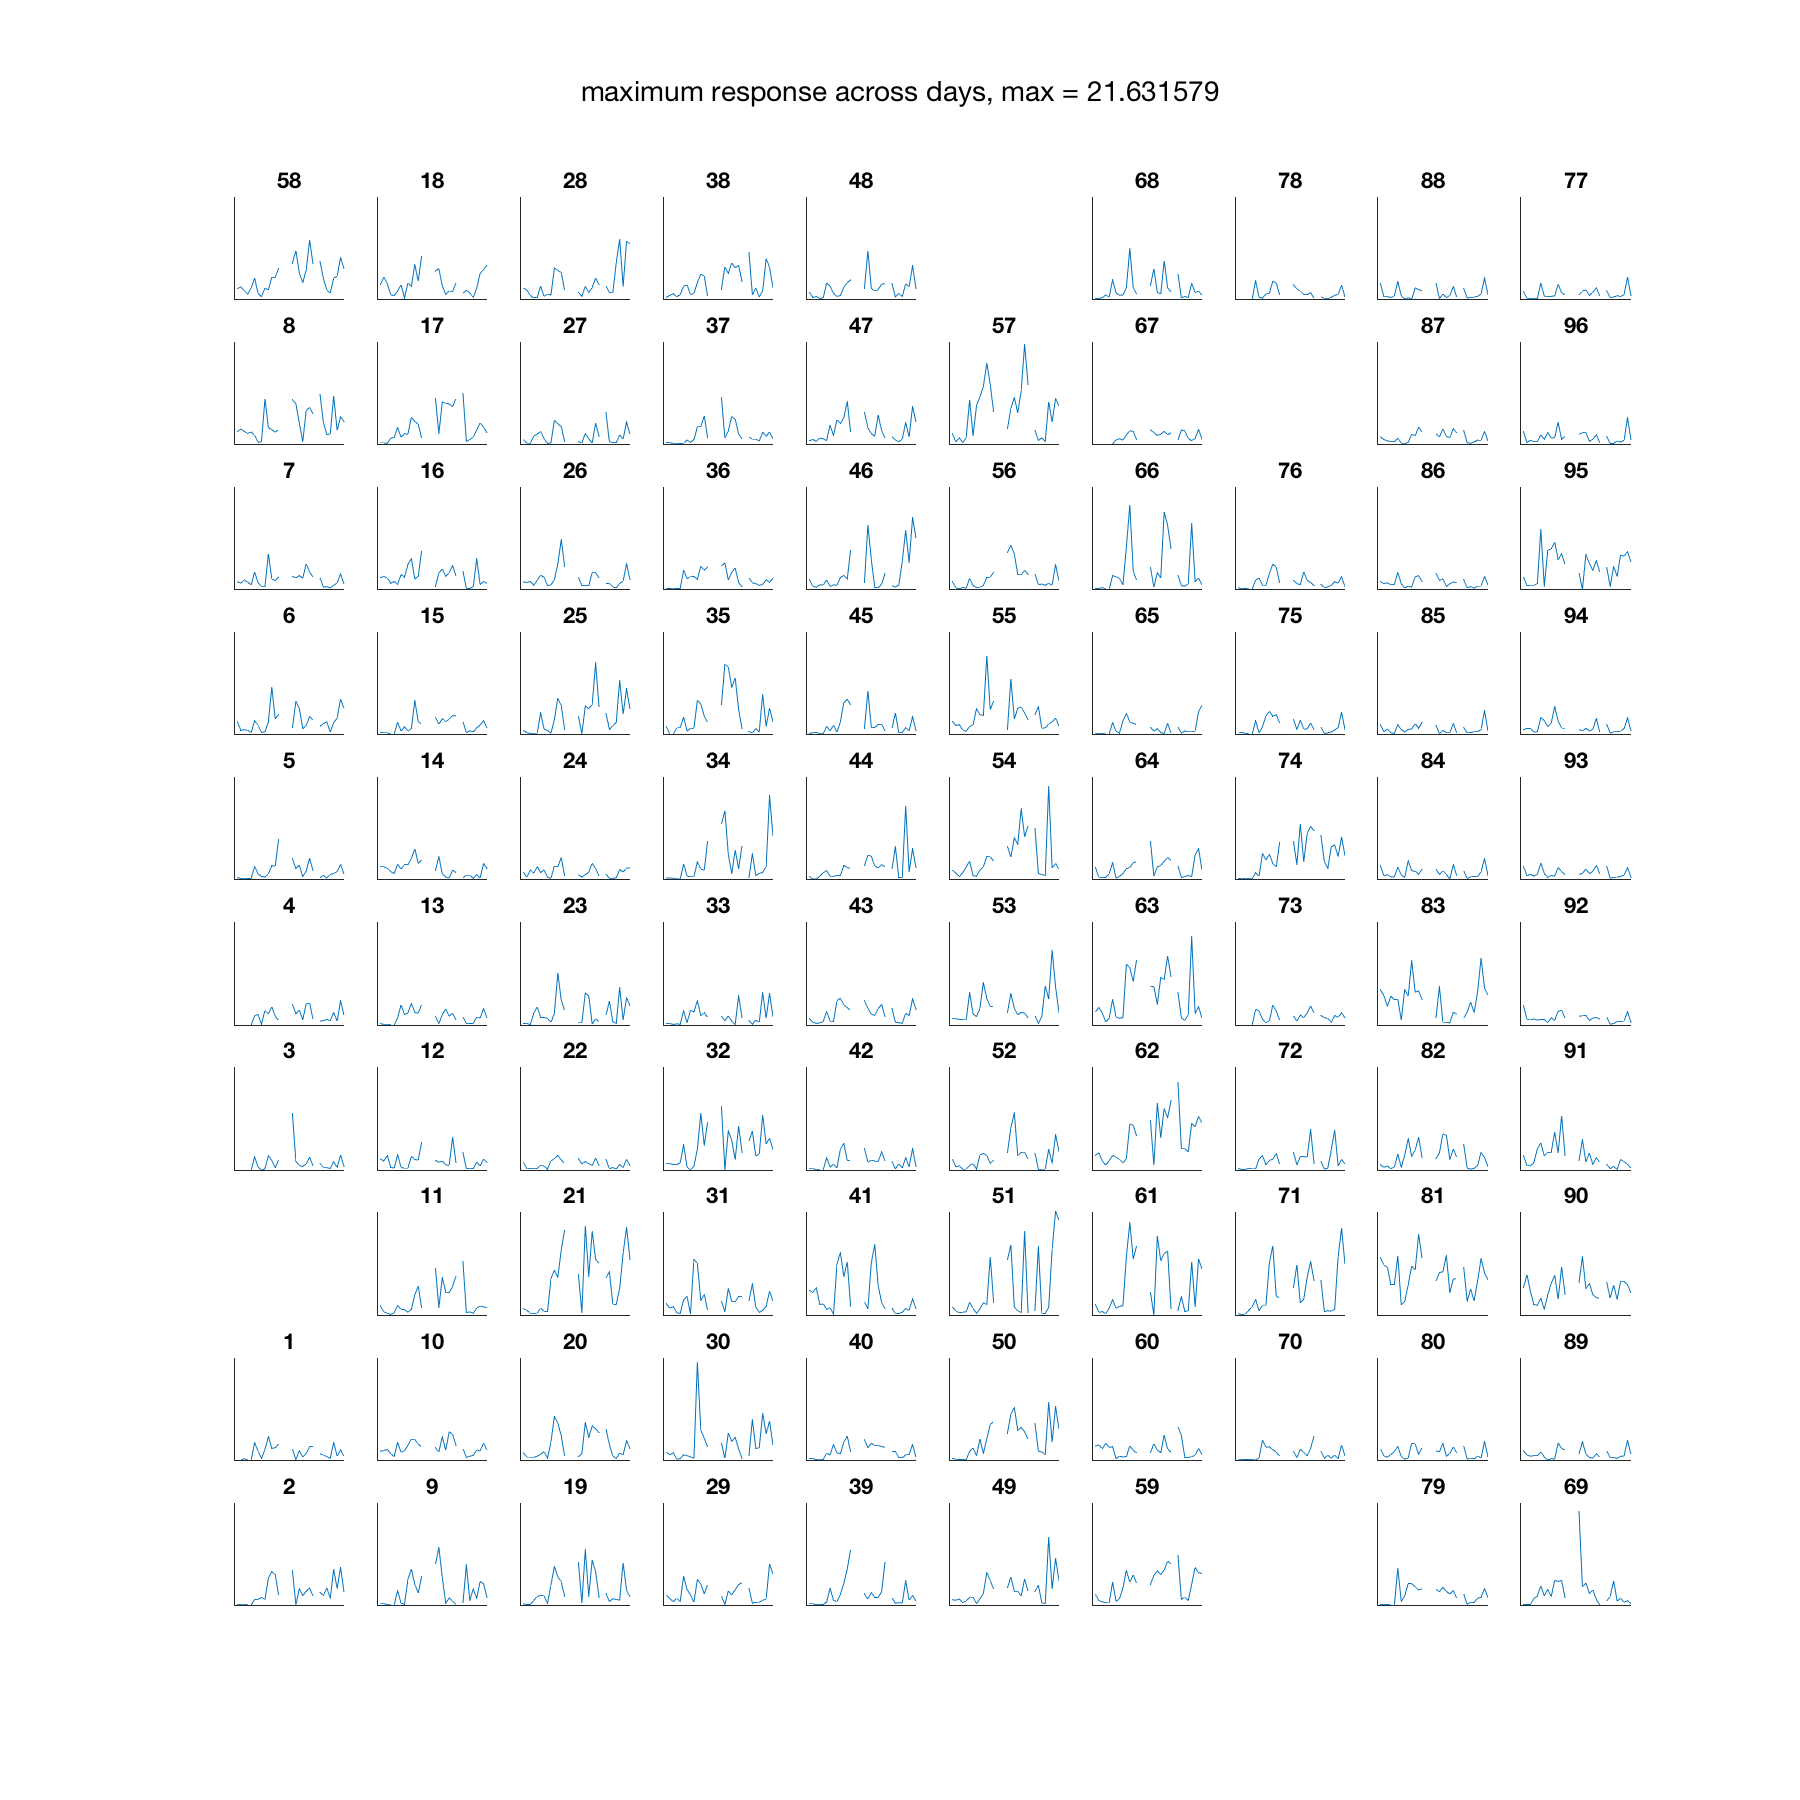

% Plot maximum response (baseline subtracted) for each channel across days
figure; hold on
pos = get(gcf,'Position');
set(gcf,'Position',[pos(1) pos(2) 900 900])
for iC = 1:nChan
    nsubplot(10, 10, A.aMap.row(iC)+1, A.aMap.col(iC)+1);
    plot(A.maxChanResp(iC,:))
    xlim([0 nS])
    ylim([0 max(A.maxChanResp(:))])
    set(gca, 'XTick', [], 'YTick', [])
    set(gca, 'Position',get(gca, 'Position')+[0 0 0.001 0.001]);
    title(iC)
end
suptitle(sprintf('maximum response across days, max = %f', max(A.maxChanResp(:))))

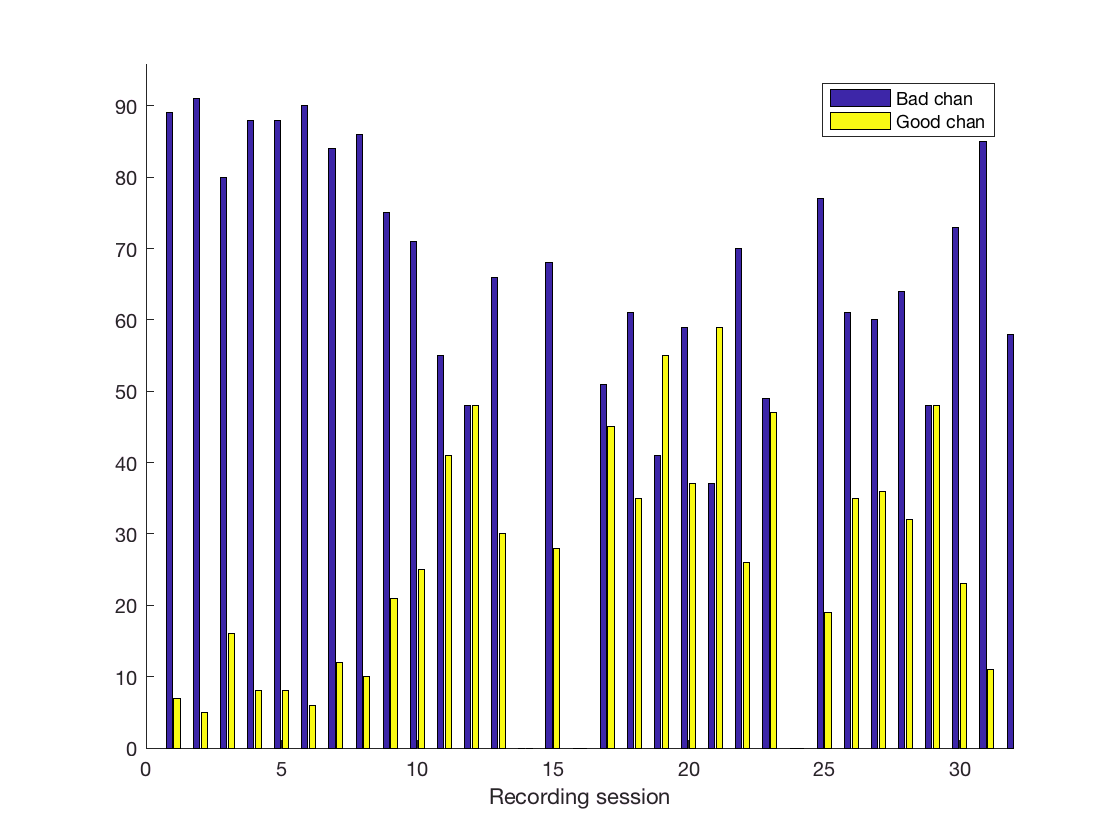

% Plot histogram of good vs bad channels for each day
figure; hold on
goodVsBadEachDay = NaN(nS,2);
for iS = 1:nS
   goodVsBadEachDay(iS,:) = [sum(A.goodChan(:,iS)==0); sum(A.goodChan(:,iS)==1)];
end
bar(goodVsBadEachDay)
legend({'Bad chan', 'Good chan'})
ylim([0 96])
xlim([0 nS])
xlabel('Recording session')

% If you want to look at some tuning or PSTH's ...
iF = 1;                                                                % Specify which recording session you want to look at
session = A.files{iF}

session = 'WU_LE_Gratings_nsp1_20170427_012'

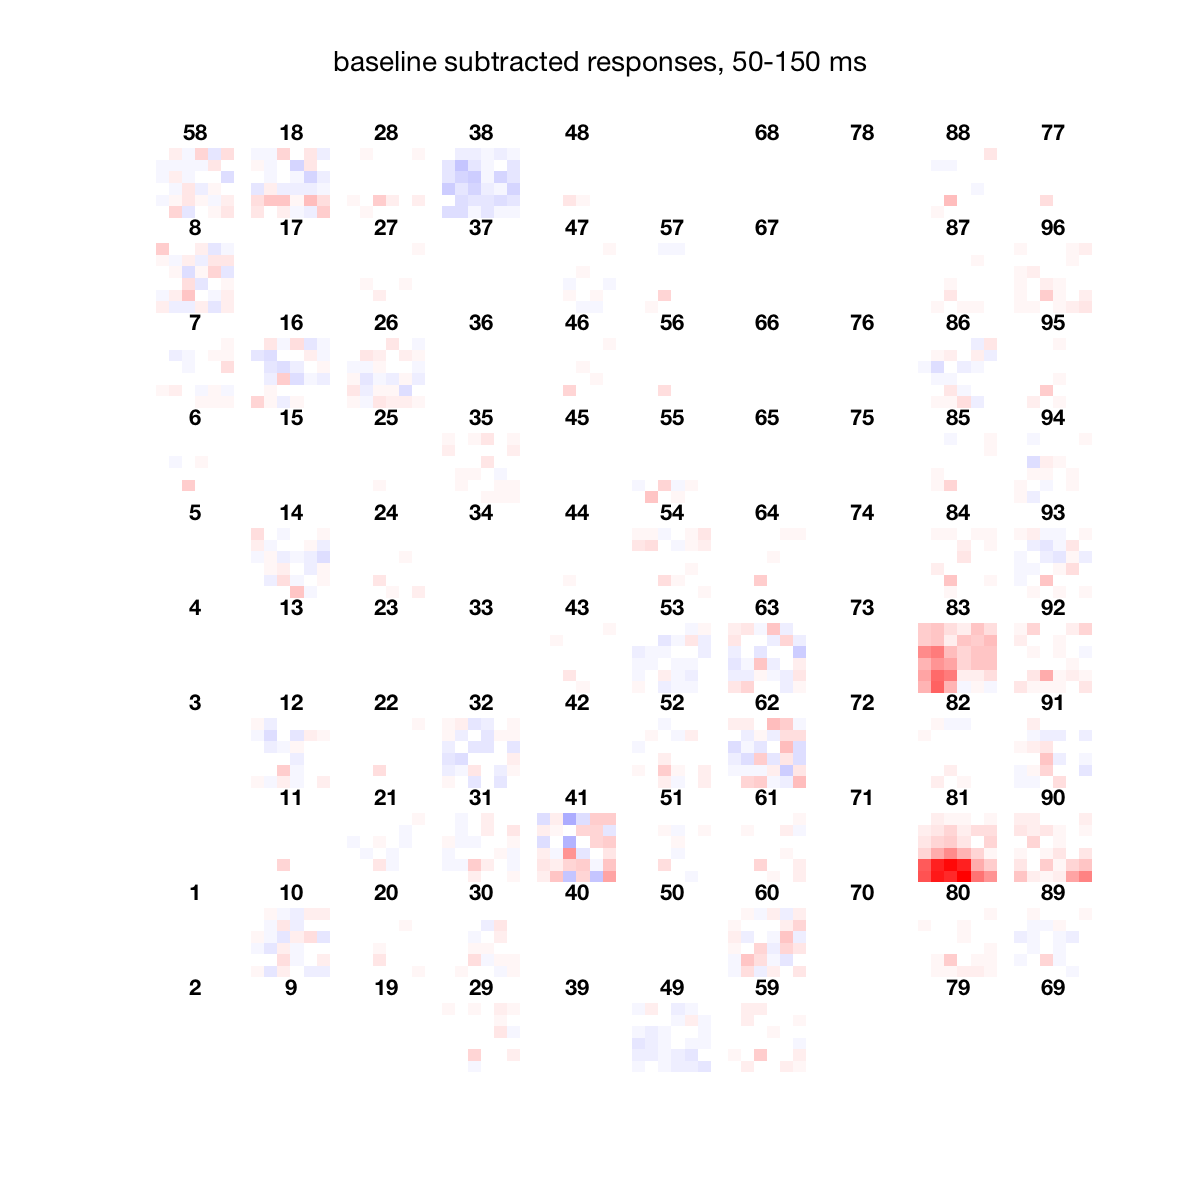


figure; hold on                                                        % Plot response matrices
pos = get(gcf,'Position');
set(gcf,'Position',[pos(1) pos(2) 600 600])
maxSessResp = max(A.maxChanResp(:,iF));
colorax = [-maxSessResp maxSessResp];
%colorax = [-10 10];
for iC = 1:nChan
    nsubplot(10, 10, A.aMap.row(iC)+1, A.aMap.col(iC)+1);
    imagesc(A.respBinned(:,:,iC,iF));
    axis tight; axis off
    colormap redblue; caxis(colorax)
    set(gca, 'Position',get(gca, 'Position')+[0 0 0.005 0.005]);
    title(iC)
end
suptitle('baseline subtracted responses, 50-150 ms')

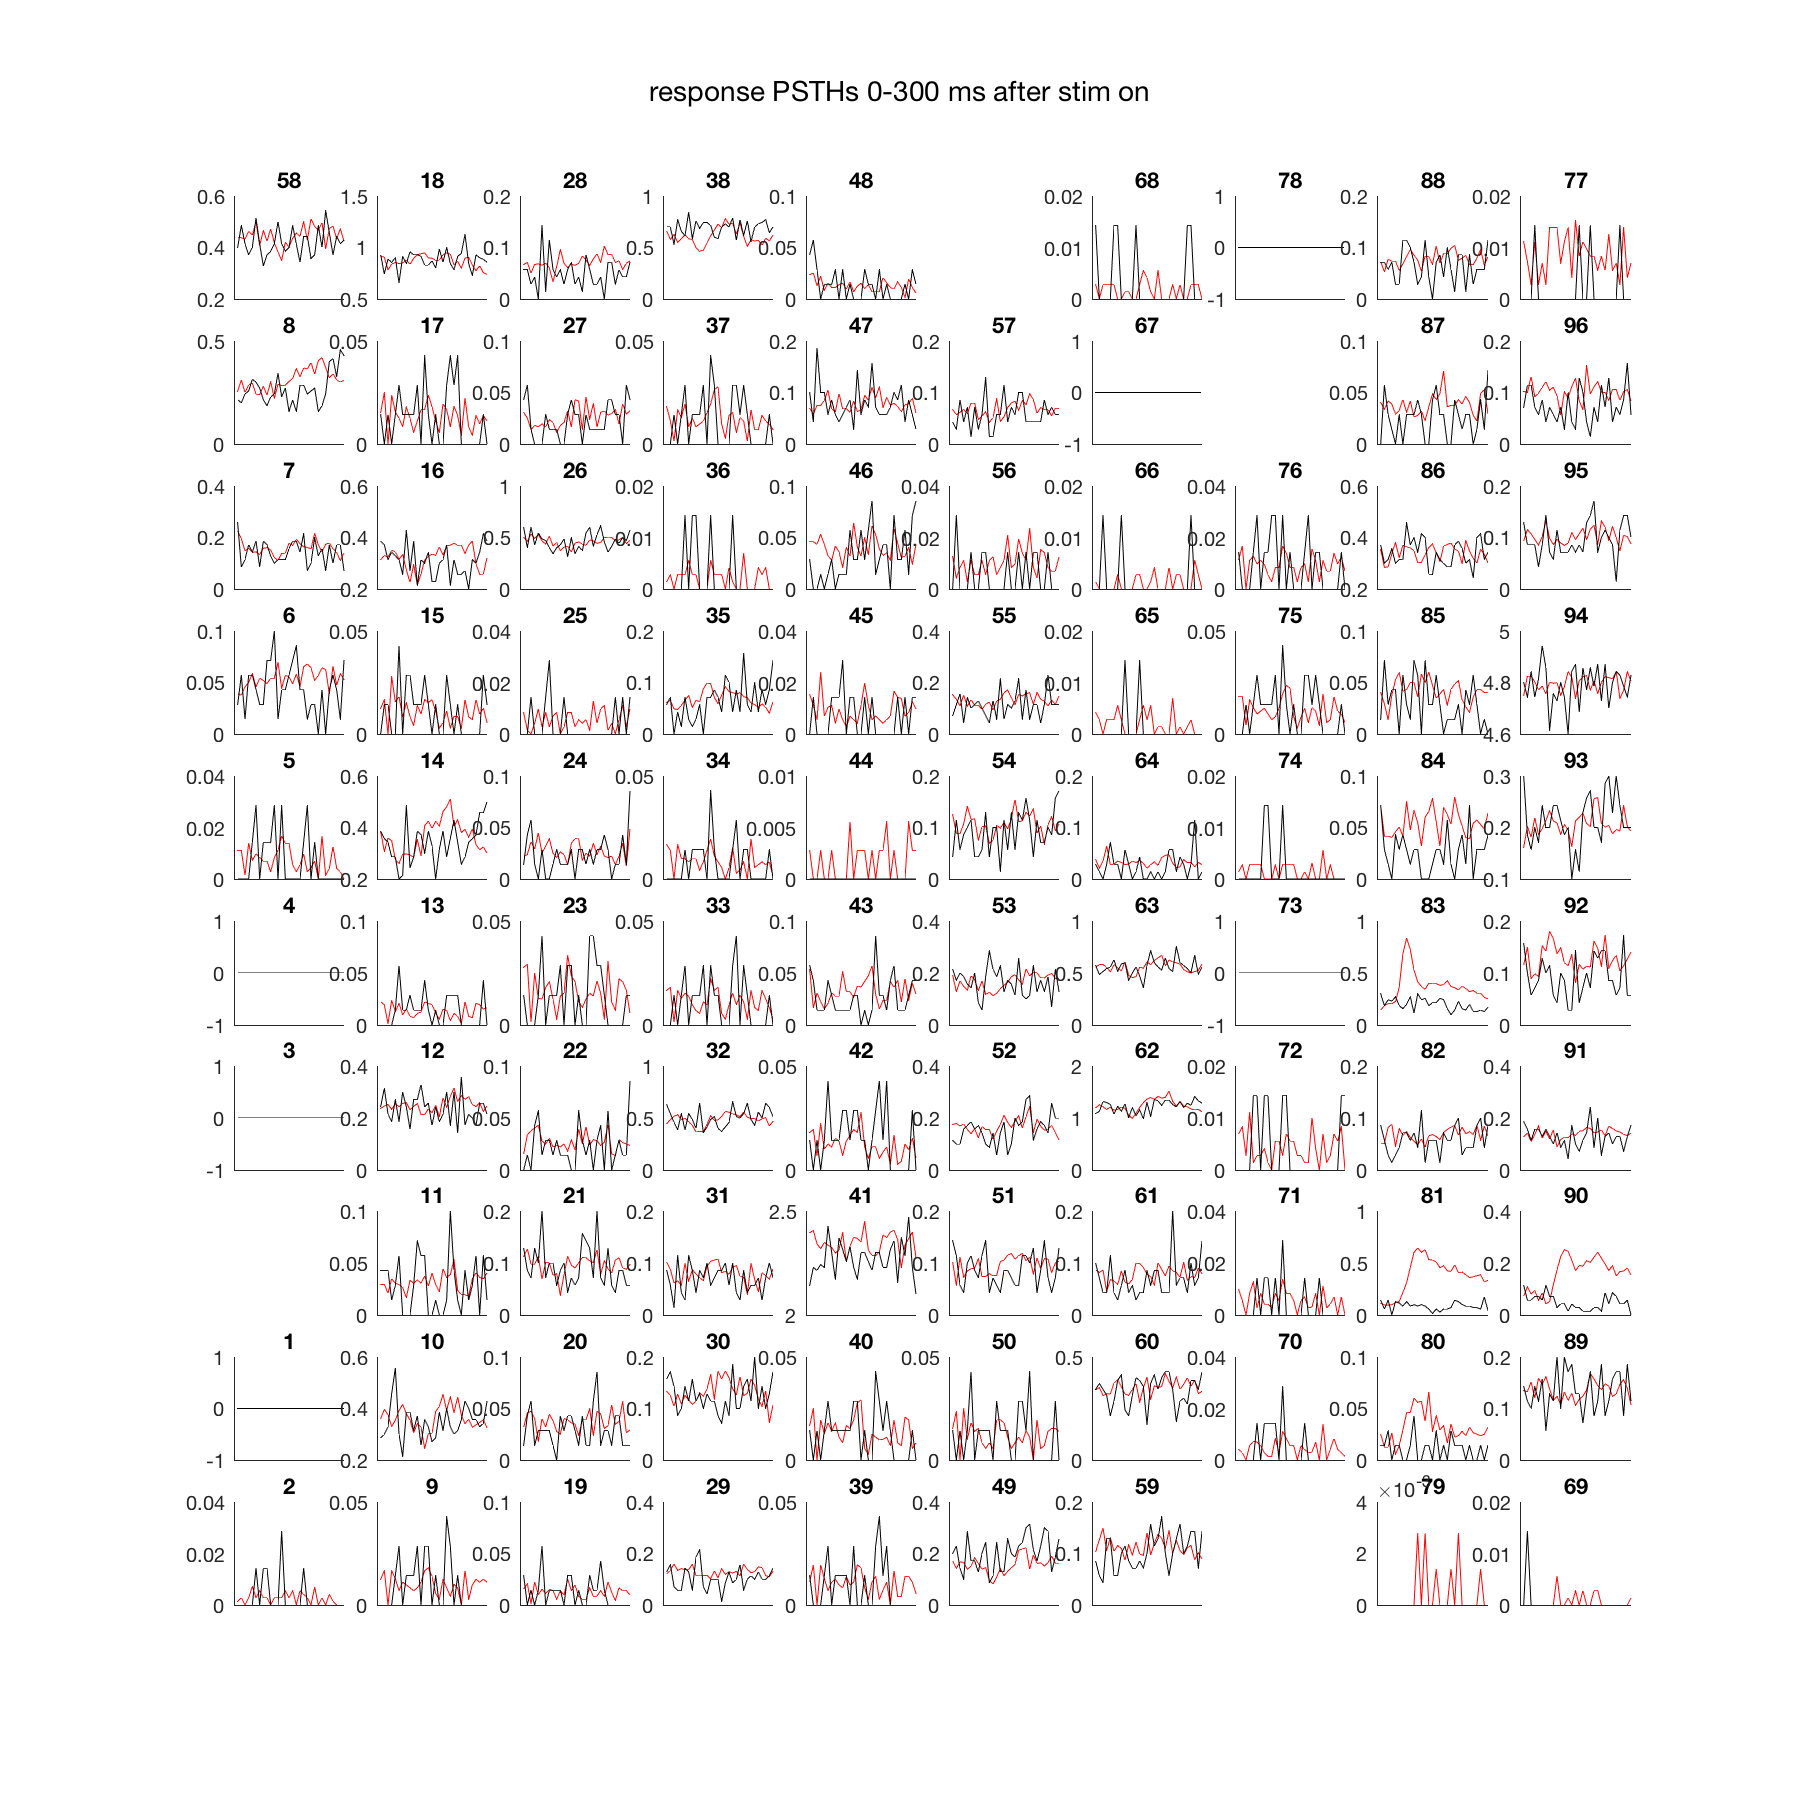


figure; hold on                                                        % Plot PSTHs
pos = get(gcf,'Position');
set(gcf,'Position',[pos(1) pos(2) 900 900])
maxSessResp = max(max([A.respAvgOverTime(:,:,iF) A.respBlankOverTime(:,:,iF)]));
for iC = 1:nChan
    nsubplot(10, 10, A.aMap.row(iC)+1, A.aMap.col(iC)+1);
    hold on
    plot(A.respAvgOverTime(:,iC,iF), 'r');
    plot(A.respBlankOverTime(:,iC,iF), 'k');
    xlim([0 30]);
    set(gca, 'XTick', [])
    %ylim([0 maxSessResp]);
    %axis off
    set(gca, 'Position',get(gca, 'Position')+[0 0 0.001 0.001]);
    title(iC)
end
suptitle('response PSTHs 0-300 ms after stim on')
export_fig([figureDir A.files{iF} '_psth.pdf'] );